clc
clear
path='\\sf3.bss.phy.private.cam.ac.uk\cicutagroup\yz655\modelling\circle_videos\paper_videos\combined_Analysis\';
filename='combined_nonAvgIqtau_angle_Iqtau.mat';
filename='large_two_waves_nonAvgIqtau_angle_Iqtau.mat';
input=[path filename];
load(input)

angle_num=size(angle_Iqtau,1);
qVec=1:size(angle_Iqtau,2);
q_num=size(angle_Iqtau,2);
tVec=1:size(angle_Iqtau,3);
t_num=size(angle_Iqtau,3);

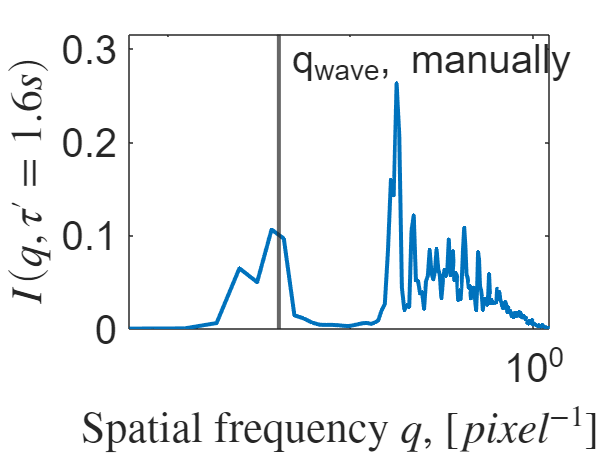

tau=16;
wavenumber=31*0.15*sqrt(2);
scale=1024;
q_max=200;
fps=10;
plotIq_all_dirc_selected_tau(angle_Iqtau,tau,path,wavenumber,scale,q_max,fps)

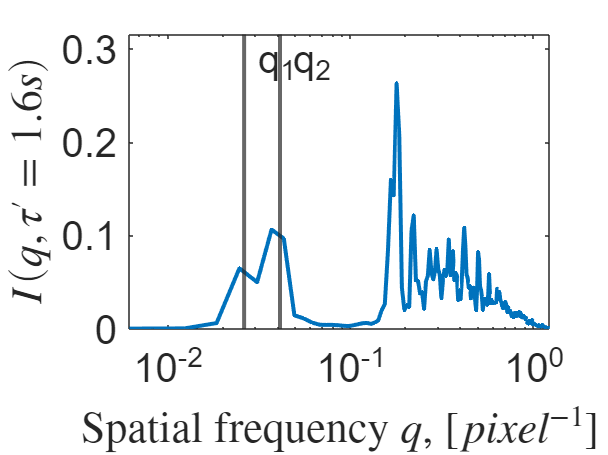

qVec=1:size(angle_Iqtau,2);
fig=figure();
y=sum(angle_Iqtau(:,1:q_max,tau),1);
    
%% for circle model videos
semilogx(qVec(1:q_max)*2*pi/scale,squeeze(y),"LineWidth",2)
hxl = xline(3*sqrt(2)*2*pi/scale,'-',{'q_{1}'},'LabelOrientation','horizontal','LineWidth',2);
hxl2 = xline(1/0.15*2*pi/scale,'-',{'q_{2}'},'LabelOrientation','horizontal','LineWidth',2);
% lambda=32;
% hxl_g = xline(lambda/scale,'-',{'q_{grid}'},'LabelOrientation','horizontal','LineWidth',1);
hxl.FontSize = 20;
hxl2.FontSize = 20;
%     hxl_g.FontSize=20;
%     ylim([0 1.2*max(y_avg)]);
ylim([0 1.2*max(y)]);
xticks([0.01 0.1 1])
set(gca,'fontsize', 20); 
%%   for all videos
xlabel('Spatial frequency $q$, [$pixel^{-1}$]','Interpreter','latex')
ylabel(['$I(q,\tau''=' num2str(round(tau/fps,2)) 's)$'],'Interpreter','latex')

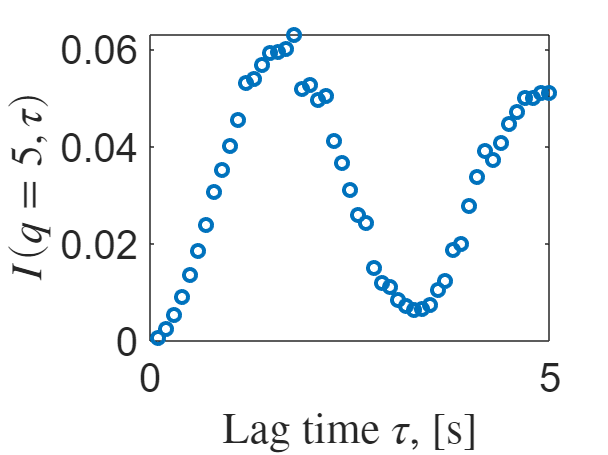

q = 5;
fps = 10;
x = tVec/fps;
y = squeeze(sum(angle_Iqtau(:,q,:),1));
figure()
plot(x,y,'o','LineWidth',2)

xlim([0 5]);
set(gca,'fontsize', 20); 
xlabel('Lag time $\tau$, [s]','Interpreter','latex')
ylabel(['$I(q=$' int2str(q) '$,\tau)$'],'Interpreter','latex')

path='\\sf3.bss.phy.private.cam.ac.uk\cicutagroup\yz655\modelling\circle_videos\paper_videos\combined_Analysis\';
filename='combined_nonAvgIqtau.mat';
filename='large_two_waves_nonAvgIqtau.mat';
input=[path filename];
load(input)

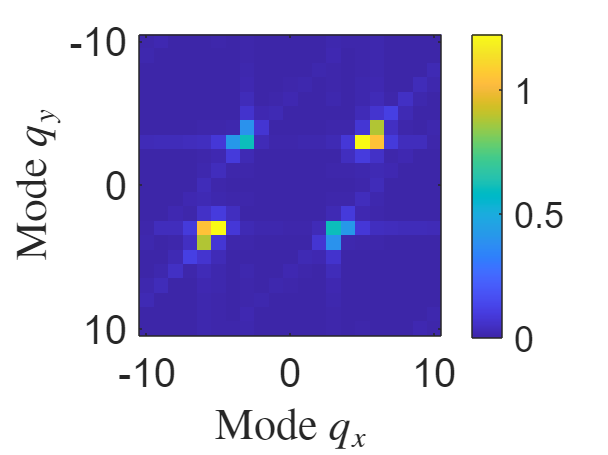

q_range=10;
radius=scale/2+1;
fig=figure();

a=fftshift(nonAvgIqtau(:,:,tau));
a(radius,radius)=0;
%     a=a';
a(radius,radius,tau)=0;
imagesc(a(radius-q_range:radius+q_range,radius-q_range:radius+q_range), 'XData', [-q_range q_range], 'YData', [-q_range q_range]);
%     hold on;

%     x = -q_range:0.1:q_range;
%     y = x*tan(-theta);
%     z = x/tan(theta);
%     plot(x,y,'LineStyle','--','Color','white','LineWidth',1,'Tag','perpendicular')
%     plot(x,z,'LineStyle','-','Color','white','LineWidth',1,'Tag','direction')
%     hold on;
% viscircles([0,0],wavenumber,'Color',[1,1,1,0.2],'LineStyle','-','LineWidth',3);
% text(x(end),y(end),'perpendicular');
set(gca,'dataAspectRatio',[1 1 1])
colorbar;
xlabel('Mode $q_x$','Interpreter','latex');
ylabel('Mode $q_y$','Interpreter','latex');
set(gca,'fontsize', 20);